
=== Running Experiment 1 ===


cfg = struct with fields:
    mm: 'sgdm'
    lr: 0.1100
    mb: 256


    mm: 'sgdm'
    lr: 0.1100
    mb: 256




=== Running Training 1 ===

=== Done Training 1 ===


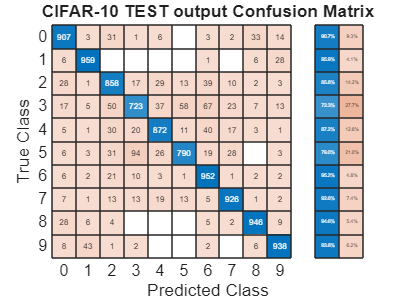

Overall Accuracy (from CM): 88.71%


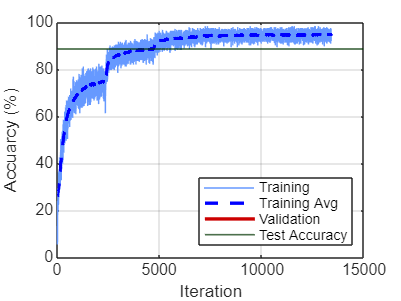

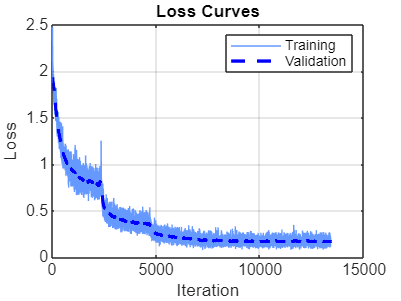


=== Running Experiment 2 ===


cfg = struct with fields:
    mm: 'sgdm'
    lr: 0.1200
    mb: 256


    mm: 'sgdm'
    lr: 0.1200
    mb: 256




=== Running Training 2 ===

=== Done Training 2 ===


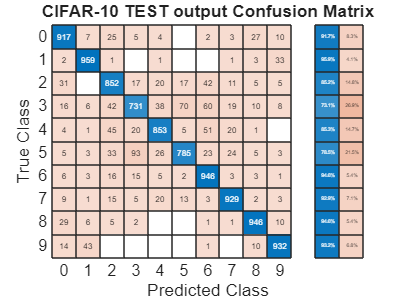

Overall Accuracy (from CM): 88.5%


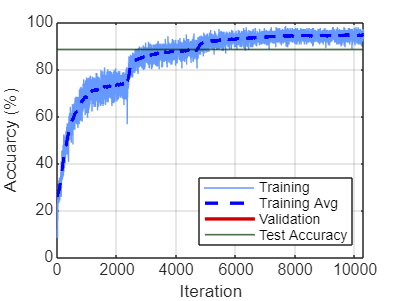

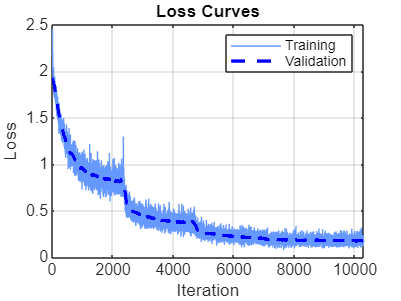


=== Running Experiment 3 ===


cfg = struct with fields:
    mm: 'sgdm'
    lr: 0.1300
    mb: 256


    mm: 'sgdm'
    lr: 0.1300
    mb: 256




=== Running Training 3 ===


clearvars
global options
% Define ranges
configs = [
    struct('mm','sgdm','lr',0.11,'mb',256),...
    struct('mm','sgdm','lr',0.12,'mb',256),...
    struct('mm','sgdm','lr',0.13,'mb',256),...
    struct('mm','sgdm','lr',0.14,'mb',256),...
    ];

loadtrainingdata
co = 5;
for expNum = 1:length(configs)
    fprintf('\n=== Running Experiment %d ===\n', expNum);
    clearvars -except configs co mm  ...
        options expNum ...
        trainImages valImages testImages ...
        trainLabels valLabels testLabels ...
        imageAugmenter trainDS valDS testDS 
    
    cfg = configs(expNum)
    mm = cfg.mm;
    disp(cfg)
    createTrainingOptions(cfg.mm,cfg.lr*cfg.mb/128,15,150,cfg.mb,valDS,floor(size(trainImages,4)/cfg.mb),0.9,true);
    conv5layers
    runfile
end